% PB
%P1
fprintf("Interpolare Lagrange:");

Interpolare Lagrange:

x = 1.001;
fprintf("f(%f) = %f", x, interpolare_Lagrange([1 2 3], [4 5 6], x));

f(1.001000) = 4.001000



%P2
fprintf("Reprezentarea grafică:");

Reprezentarea grafică:

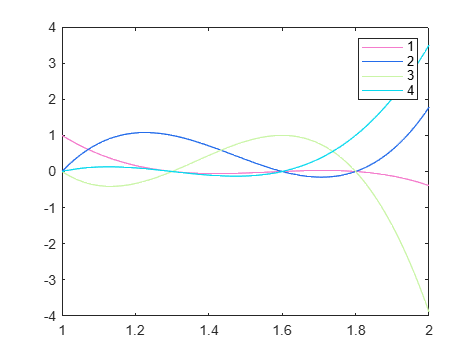

nodes = [1 1.3 1.6 1.8];
m = 4;

labels = {};
for k = 1 : m
    t = 1 : 0.01 : 2;
    p = evaluate_polynomial_multiple_points(nodes, k, t);
    labels = [labels num2str(k)];
    plot(t, p, 'color', rand(1,3))
    hold on;
end
legend(labels);
hold off;



%P3
fprintf("Reprezentarea grafică a f și Lmf (sin(x)):");

Reprezentarea grafică a f și Lmf (sin(x)):

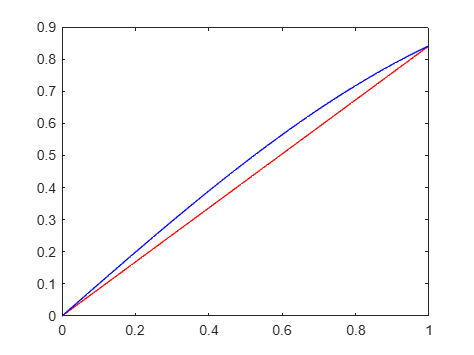

nodes = [0, 1];
nodevals = sin(nodes);

points = 0 : 0.01 : 1;
result = interpolare_Lagrange_multiple_points(nodes, nodevals, points);

plot(points, result, 'r');
hold on;

sin_result = sin(points);
plot(points, sin_result, 'b');
hold off;



%P4
fprintf("Interpolare Lagrange pentru f(x) = sin(x):");

Interpolare Lagrange pentru f(x) = sin(x):

fprintf("%f", interpolare_Lagrange_known_function(1.2, @sin, 3, [1.1 1.4 1.6]));

0.932362



%P5
fprintf("Interpolare Lagrange baricentrică:");

Interpolare Lagrange baricentrică:

x = 1.001;
fprintf("f(%f) = %f", x, interpolare_Lagrange_baricentrica([1 2 3], [4 5 6], x));

f(1.001000) = 4.001000

## PROBLEME PRACTICE

#### P1. Aproximați populația SUA n 1975 și 2018.

% PB PRACTICE
%P1
% Pentru 1975:
x = [1900 1910 1920 1930 1940 1950 1960 1970 1980];
y = [75995 91972 105711 123203 131669 150697 179323 203212 226505];

fprintf("Populația SUA în anul 1975:");

Populația SUA în anul 1975:

fprintf("%f", interpolare_Lagrange_baricentrica(x, y, 1975));

215759.805115


% Pentru 2018:
x = [1990 2000 2010];
y = [249633 281422 308786];

fprintf("Populația SUA în anul 2018:");

Populația SUA în anul 2018:

fprintf("%f", interpolare_Lagrange_baricentrica(x, y, 2018));

327491.200000



%P2
f = @(x)exp(x.^2 - 1);
x = 1.25;
fprintf("f(%f) = %f", x, interpolare_Lagrange_known_function(x, f, 4, [1 1.1 1.2 1.3 1.4]));

f(1.250000) = 1.755675

fprintf("!!f(%f) = %f", x, exp(x.^2 - 1));

!!f(1.250000) = 1.755055



%P5
fprintf("Aproximarea sin(5):\n");

Aproximarea sin(5):


x = 5;
fprintf("f(%f) = %f\n", x, interpolare_Lagrange_known_function(x, @sin, 4, [3 4 6 7]));

f(5.000000) = -0.823830


fprintf("sin(%f) = %f\n", x, sin(x));

sin(5.000000) = -0.958924



fprintf("\nAproximarea cos(5):\n");


Aproximarea cos(5):


x = 5;
fprintf("f(%f) = %f\n", x, interpolare_Lagrange_known_function(x, @cos, 4, [3 4 6 7]));

f(5.000000) = 0.243699


fprintf("cos(%f) = %f\n", x, cos(x));

cos(5.000000) = 0.283662


Interpolarea Lagrange pentru puncte, noduri și valori date:

function [val] = interpolare_Lagrange(nodes, nodevals, point)
    
    val = 0;
    
    [~, cols] = size(nodes);
    m = cols;
    x = point;
    
    for k = 1 : m
       % Calculam f(xk)
       f = nodevals(1, k);
       u = 1; 
       d = 1;
       for j = 1 : m
          if (j ~= k)
              % Calculam x - xj
              u = u * (x - nodes(1, j));
              % Calculam xk - xj
              d = d * (nodes(1, k) - nodes(1, j));
          end
       end
       
       val = val + f * (u / d);

    end

end

function [vals] = interpolare_Lagrange_multiple_points(nodes, nodevals, points)

    vals = zeros(size(points));
    [~, col] = size(points);
    for i = 1 : col
       vals(1, i) = interpolare_Lagrange(nodes, nodevals, points(1, i)); 
    end

end

function [val] = interpolare_Lagrange_known_function(x, f, m, nodes)

    considered = nodes(1 : m);
    consideredVals = f(considered);
    
    val = interpolare_Lagrange(considered, consideredVals, x);

end

function [val] = interpolare_Lagrange_baricentrica(nodes, nodevals, x)
    
    [~, col] = size(nodes);
    m = col;
    
    w = zeros(1, m);
    for j = 1 : m
        p = 1;
        for i = 1 : m
            if i ~= j
               p = p * (nodes(1, j) - nodes(1, i));
            end
        end
        w(1, j) = 1 / p;
    end
    
    u = 0; d = 0;
    for j = 1 : m
        u = u + (nodevals(1, j) * w(1, j)) / (x - nodes(1, j));
        d = d + w(1, j) / (x - nodes(1, j));
    end

    val = u / d;

end

function [val] = evaluate_polynomial_multiple_points(nodes, k, x)

    val = zeros(size(x));
    [~, c] = size(x);
    for i = 1 : c 
       val(1, i) = evaluate_fundamental_polynomial(nodes, k, x(1, i)); 
    end

end

function [val] = evaluate_fundamental_polynomial(nodes, k, x)
    [~, m] = size(nodes);
    u = 1; d = 1;
    for j = 1 : m
       if (j ~= k)
          % x - xj
          u = u * (x - nodes(1, j));
          % xk - xj
          d = d * (nodes(1, k) - nodes(1, j));
       end
    end
    val = u / d;
end